# Illustrating the ParTI method on gene expression in Cancer (RNAseq)

This script an example of how to analyze gene expression data with the ParTI method. It can be used as a template to analyze other datasets.

% Load the data into Matlab from a comma separated value (CSV) file
% The file is a purely numerical matrix, with patients as rows and genes as
% columns
geneExpression = dlmread('Data/SCLC_CCLE_Minna_RNA-seq_batch-corrected_geneexp_10_2020.csv', ',');
geneExpression = geneExpression'

geneExpression =     2.1184    2.8811    0.7925    0.6898    1.2871    2.2260    0.7037    5.2148    7.5287    0.6369    0.6767    0.7476    0.6569    2.6042    5.9720    3.2210    3.3926    6.4990    0.9869    4.5959    2.1465    2.6806    4.9120    3.4362    5.4121    2.8571    3.1472    6.0744    1.0046    1.2619    2.2036    1.3451    4.7939    5.5269    0.6801    4.3100    0.6964    4.2651    0.6352    0.7225    6.3570    4.5709    0.6619    2.3680    0.8405    3.9695    4.8383    3.9279    3.9168    1.5225
    5.2816    1.0840    0.6290    0.6898    0.6180    5.3831    0.9575    5.9854    4.8075    0.7072    0.7333    0.6635    0.6569    3.3386    6.0128    3.9775    6.1192    7.0414    0.6705    5.7715    0.7279    3.6972    5.4484    3.1390    5.8384    2.6047    3.7857    1.8689    0.7027    4.4611    0.7391    0.9539    4.5236    3.1726    1.4059    8.4065    2.7470    4.2780    1.4671    2.6987    0.7368    4.3574    0.6619    0.6000    0.6514    5.5886    4.8695    4.6346  

% The file is formated as samples (i.e. patients) x genes. 
% We load gene names.
geneNames = importdata('Data/geneNames_10_2020.csv', ',');

## We import the sample attributes, i.e. the clinical data on patients

These come in two kinds: - discrete attributes, i.e. categorical data (citizenship, gender, cancer progression grade, ...) - continuous attributes, i.e. numerical data (weight, age, tumor volume, ...) We start by loading a file with clinical attributes, both discrete and continuous.

[discrAttrNames, discrAttr] = ...
    read_enriched_csv('Data/combined_clusters_2020-05-27-MC.csv', ',');
%where discrAttr is a matrix of patients x attributes. The names of
%the attributes are stored in discrAttrNames.

% Continuous attributes are analysed using a different statistical procedure
% than discrete attributes. We therefore load a file with vectors 'discIdcs' and 
% 'contIdcs' containing the indices of discrete and continuous attributes 
% to be considered in the study:
% load Data/CancerRNAseq/CancerRNAseq_featIdcs.mat;

% We extract continous attributes, discarding the sample ID
% (the order of the clinical records matches that of the expression data)
% contAttrNames = discrAttrNames(:,contIdcs);
% contAttr = discrAttr(:,contIdcs);
% Now we convert contAttr to a matrix of doubles
% contAttr = str2double(contAttr);

% And select the remaining discrete attributes:
% discrAttrNames = discrAttrNames(:,discIdcs);
% discrAttr = discrAttr(:,discIdcs);

## We expand the sample attributes by computing changes in GO category expression

This section is optional. It makes it possible to determine broad gene expression categories that are over-expressed in the vicinity of archetypes. This is helpful to characterize the archetypes.

[GOExpression,GONames,~,GOcat2Genes] = MakeGOMatrix(geneExpression, geneNames, ...
                {'MSigDB/c2.cp.v4.0.symbols.gmt'}, ...
                10);
% GOExpression is a matrix of patients x GO categories, and
% GONames contains the name of the GO categories.
% GOcat2Genes is a boolean matrix of genes x GO categories which
% indicates, for each category, which genes were used to compute it.
% In the next line, we expand this matrix so that it has as many columns as
% the number of continuous features (clinical + GO). Because clinical
% features are typically not directly based on specific genes, we add
% zeroes in the corresponding columns:
% GOcat2Genes=[zeros(size(GOcat2Genes,1),size(discrAttr,2)),GOcat2Genes];
% % and we expand the continuous clinical features with GO-based continuous
% % features:
% contAttrNames = [contAttrNames, GONames];
% contAttr = [contAttr, GOExpression];
contAttrNames = GONames;
contAttr = GOExpression;

## Finally, we substitute underscores '_' in variable names with spaces ' '

to prevent the characters following underscores from appearing in indice position.

Starting to perform PCA, for big data on slow computers this may take a while...


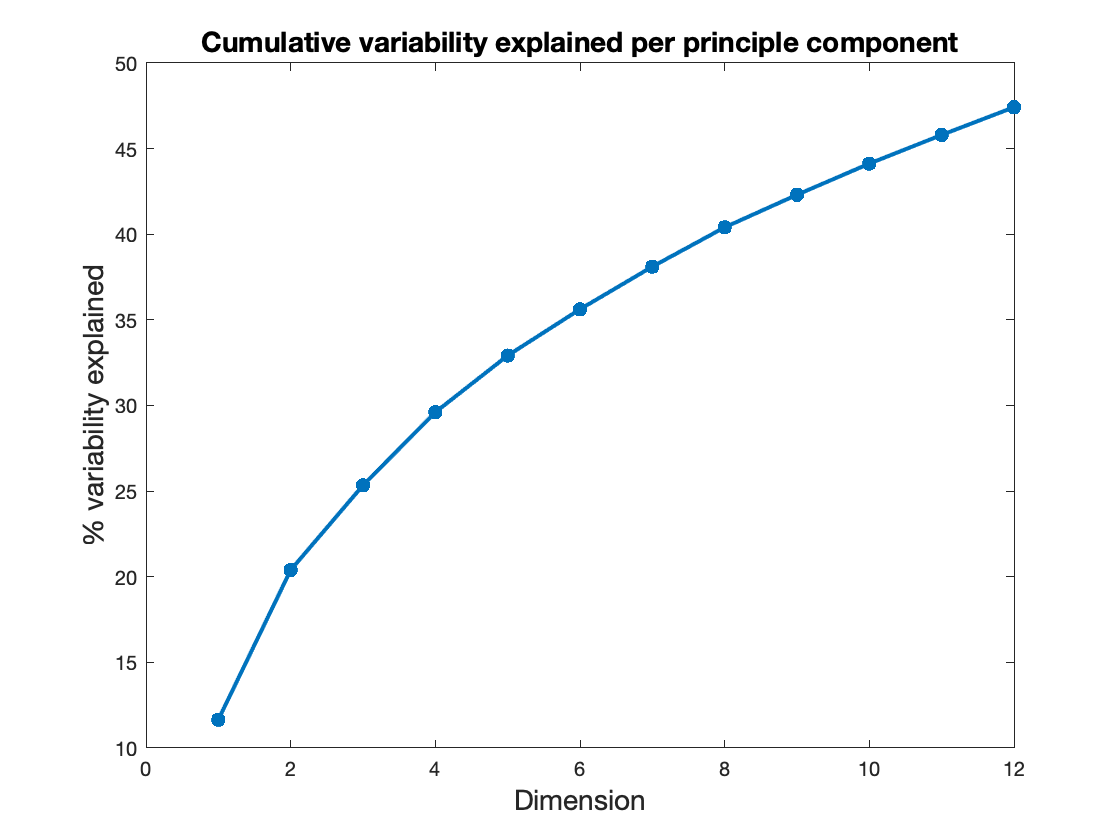

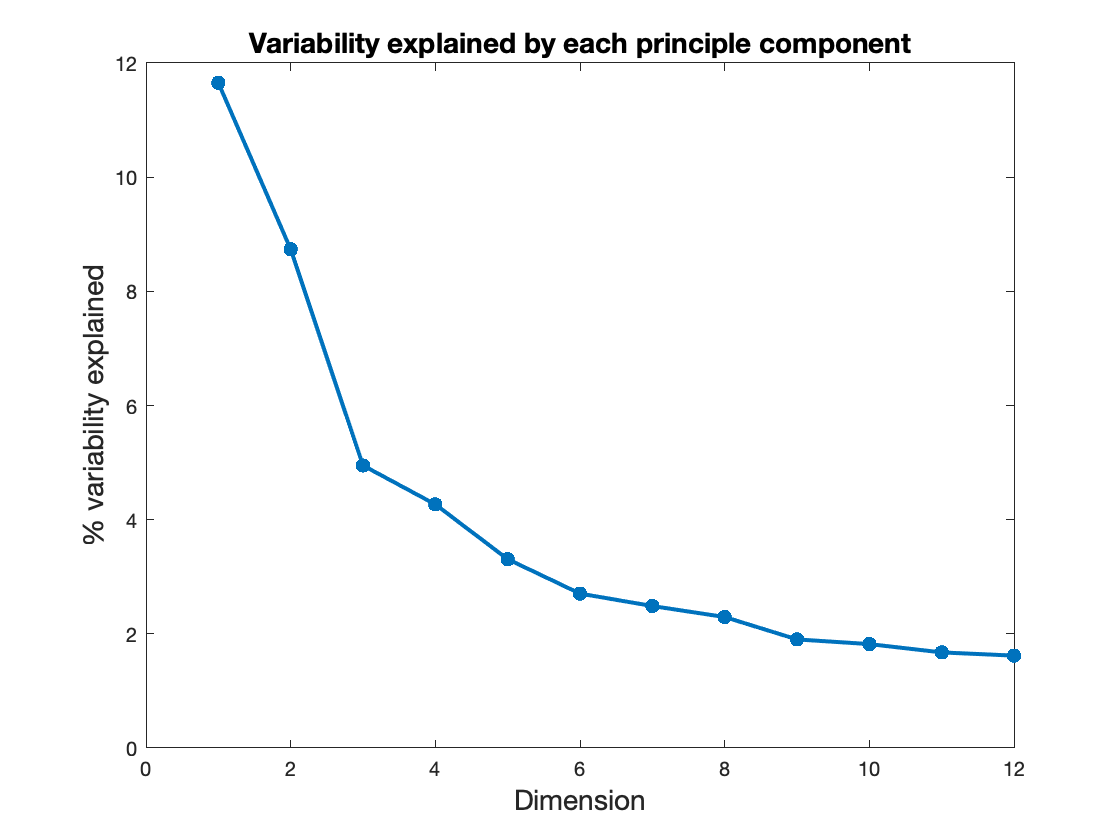

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


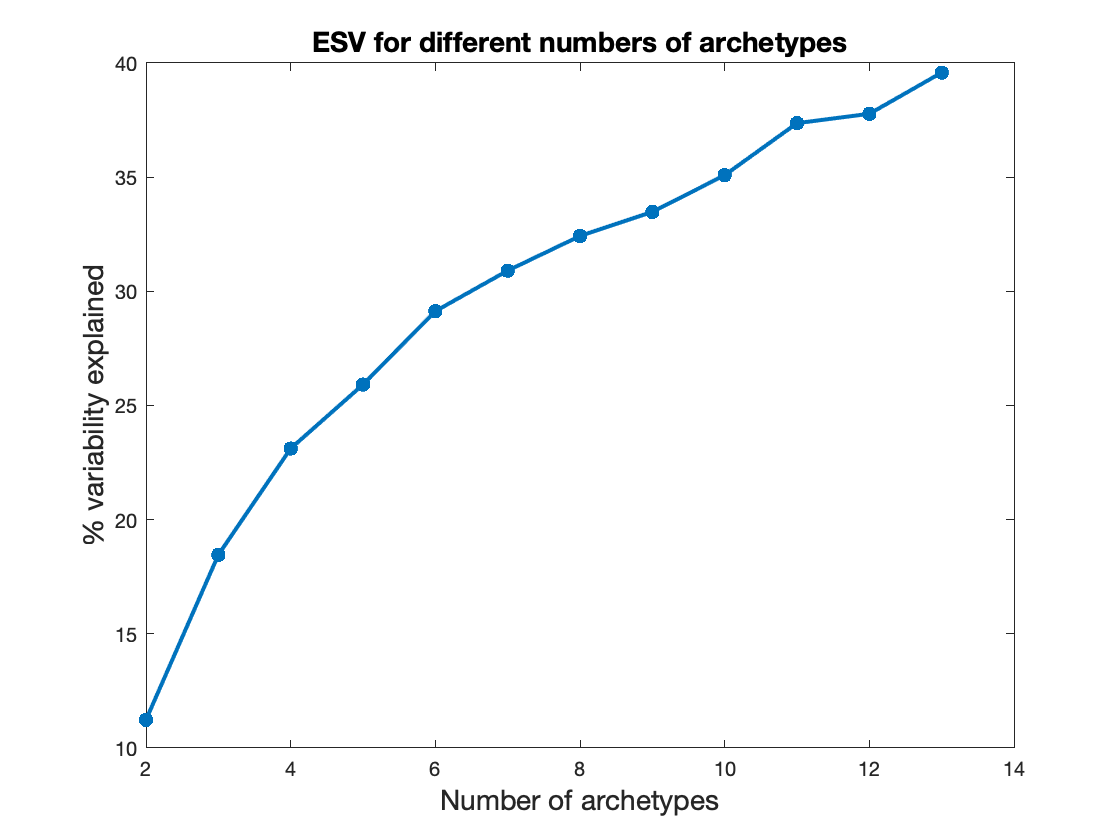

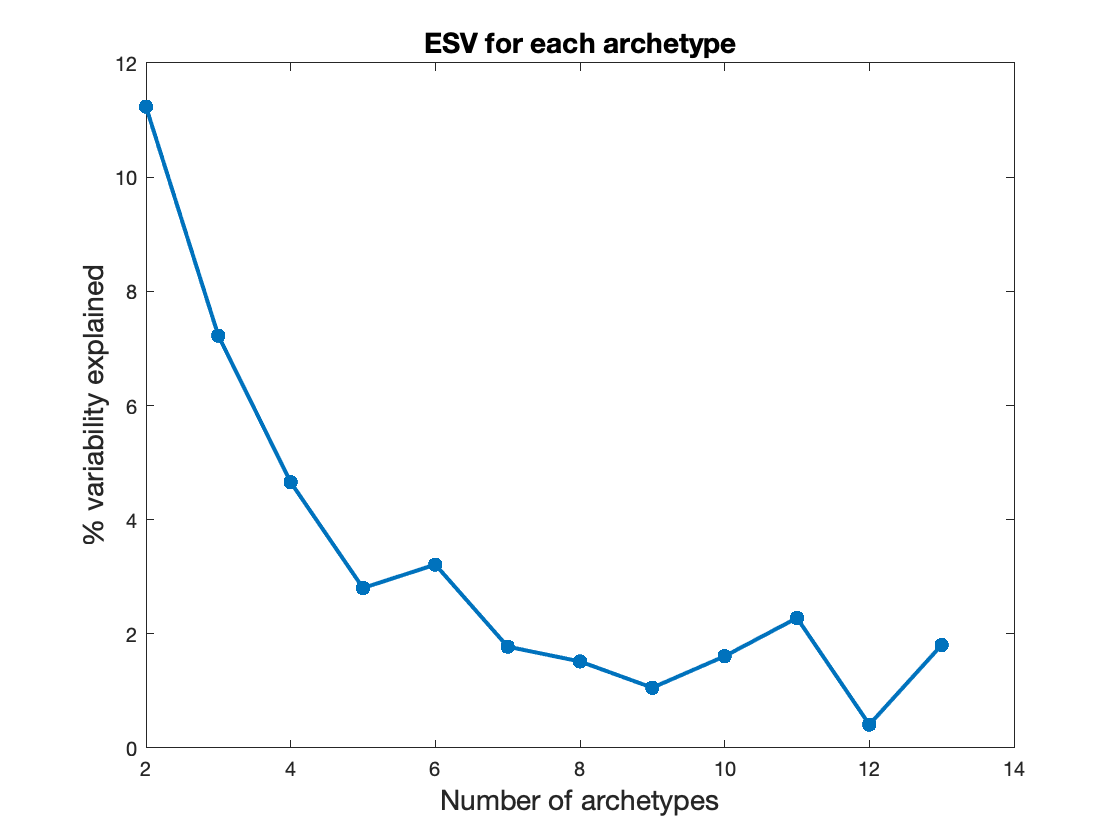

Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes


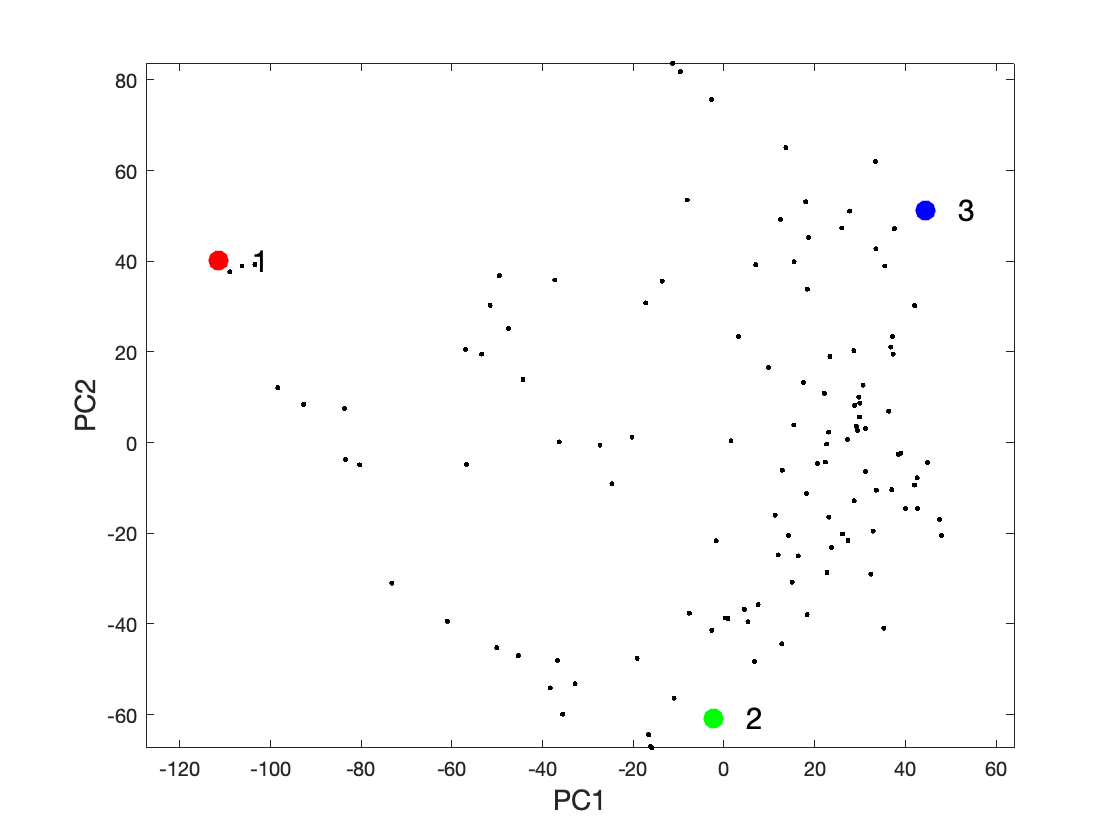

Finished sorting data points.
Your data was divided into 10 bins.


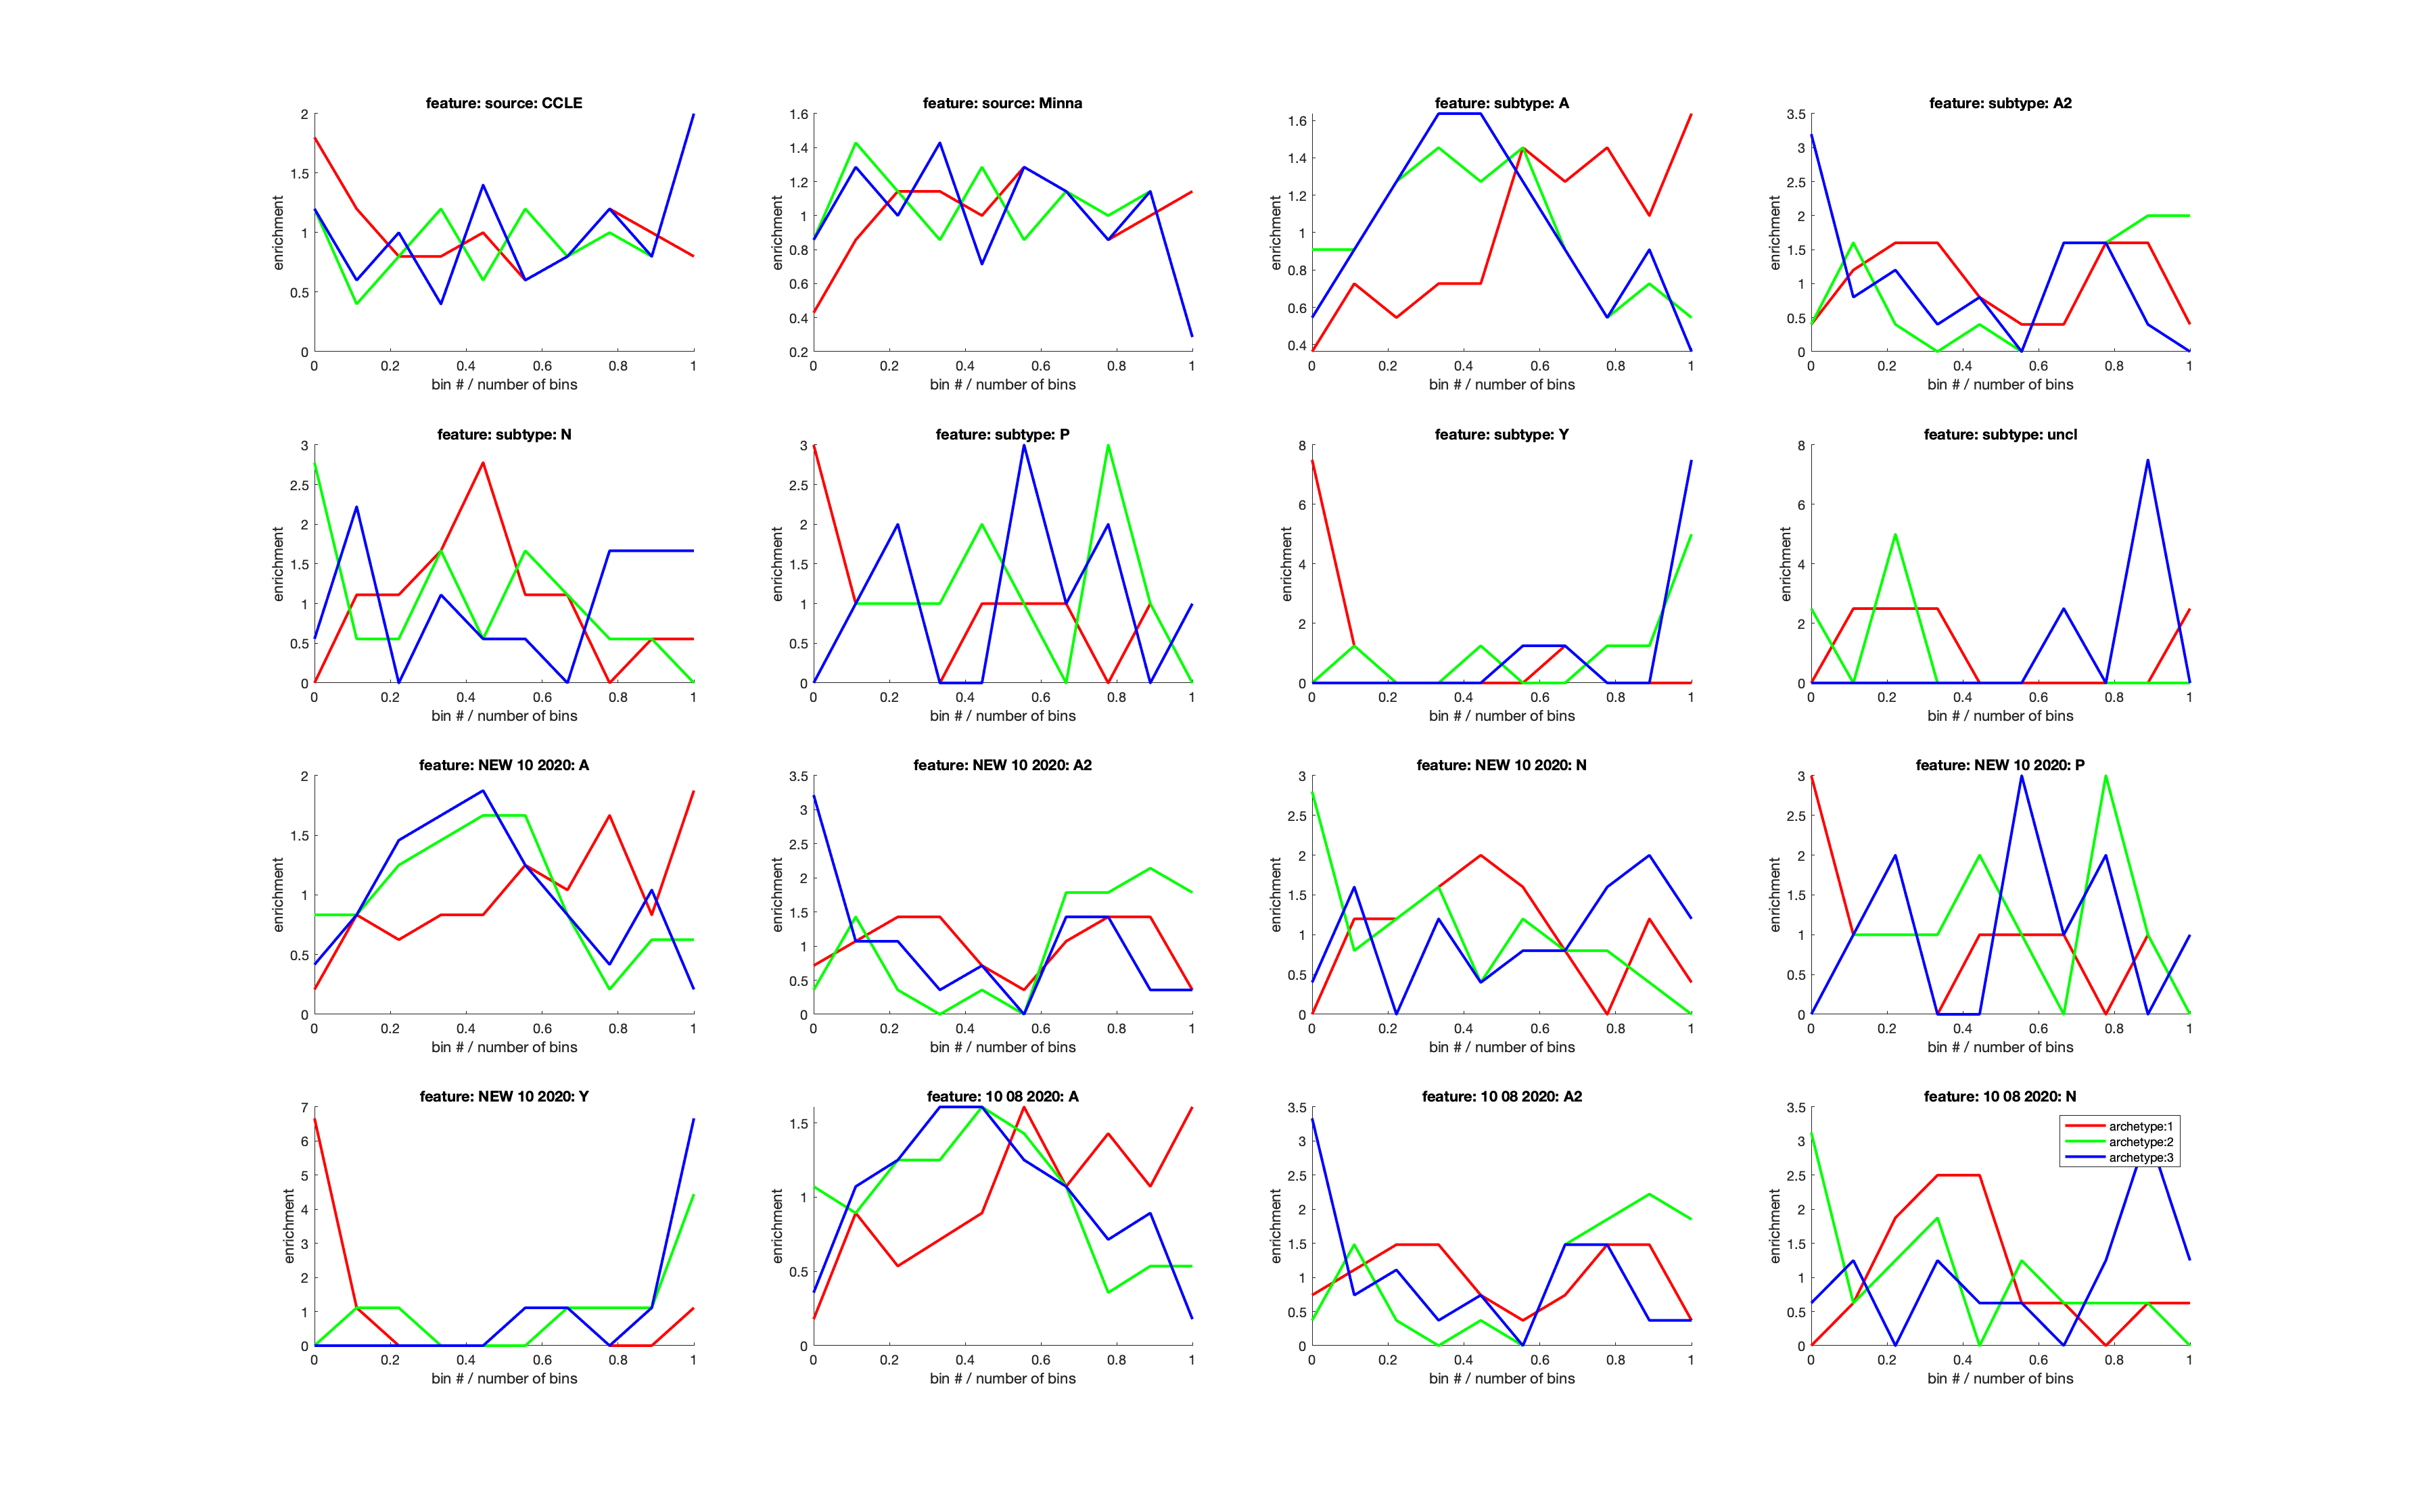

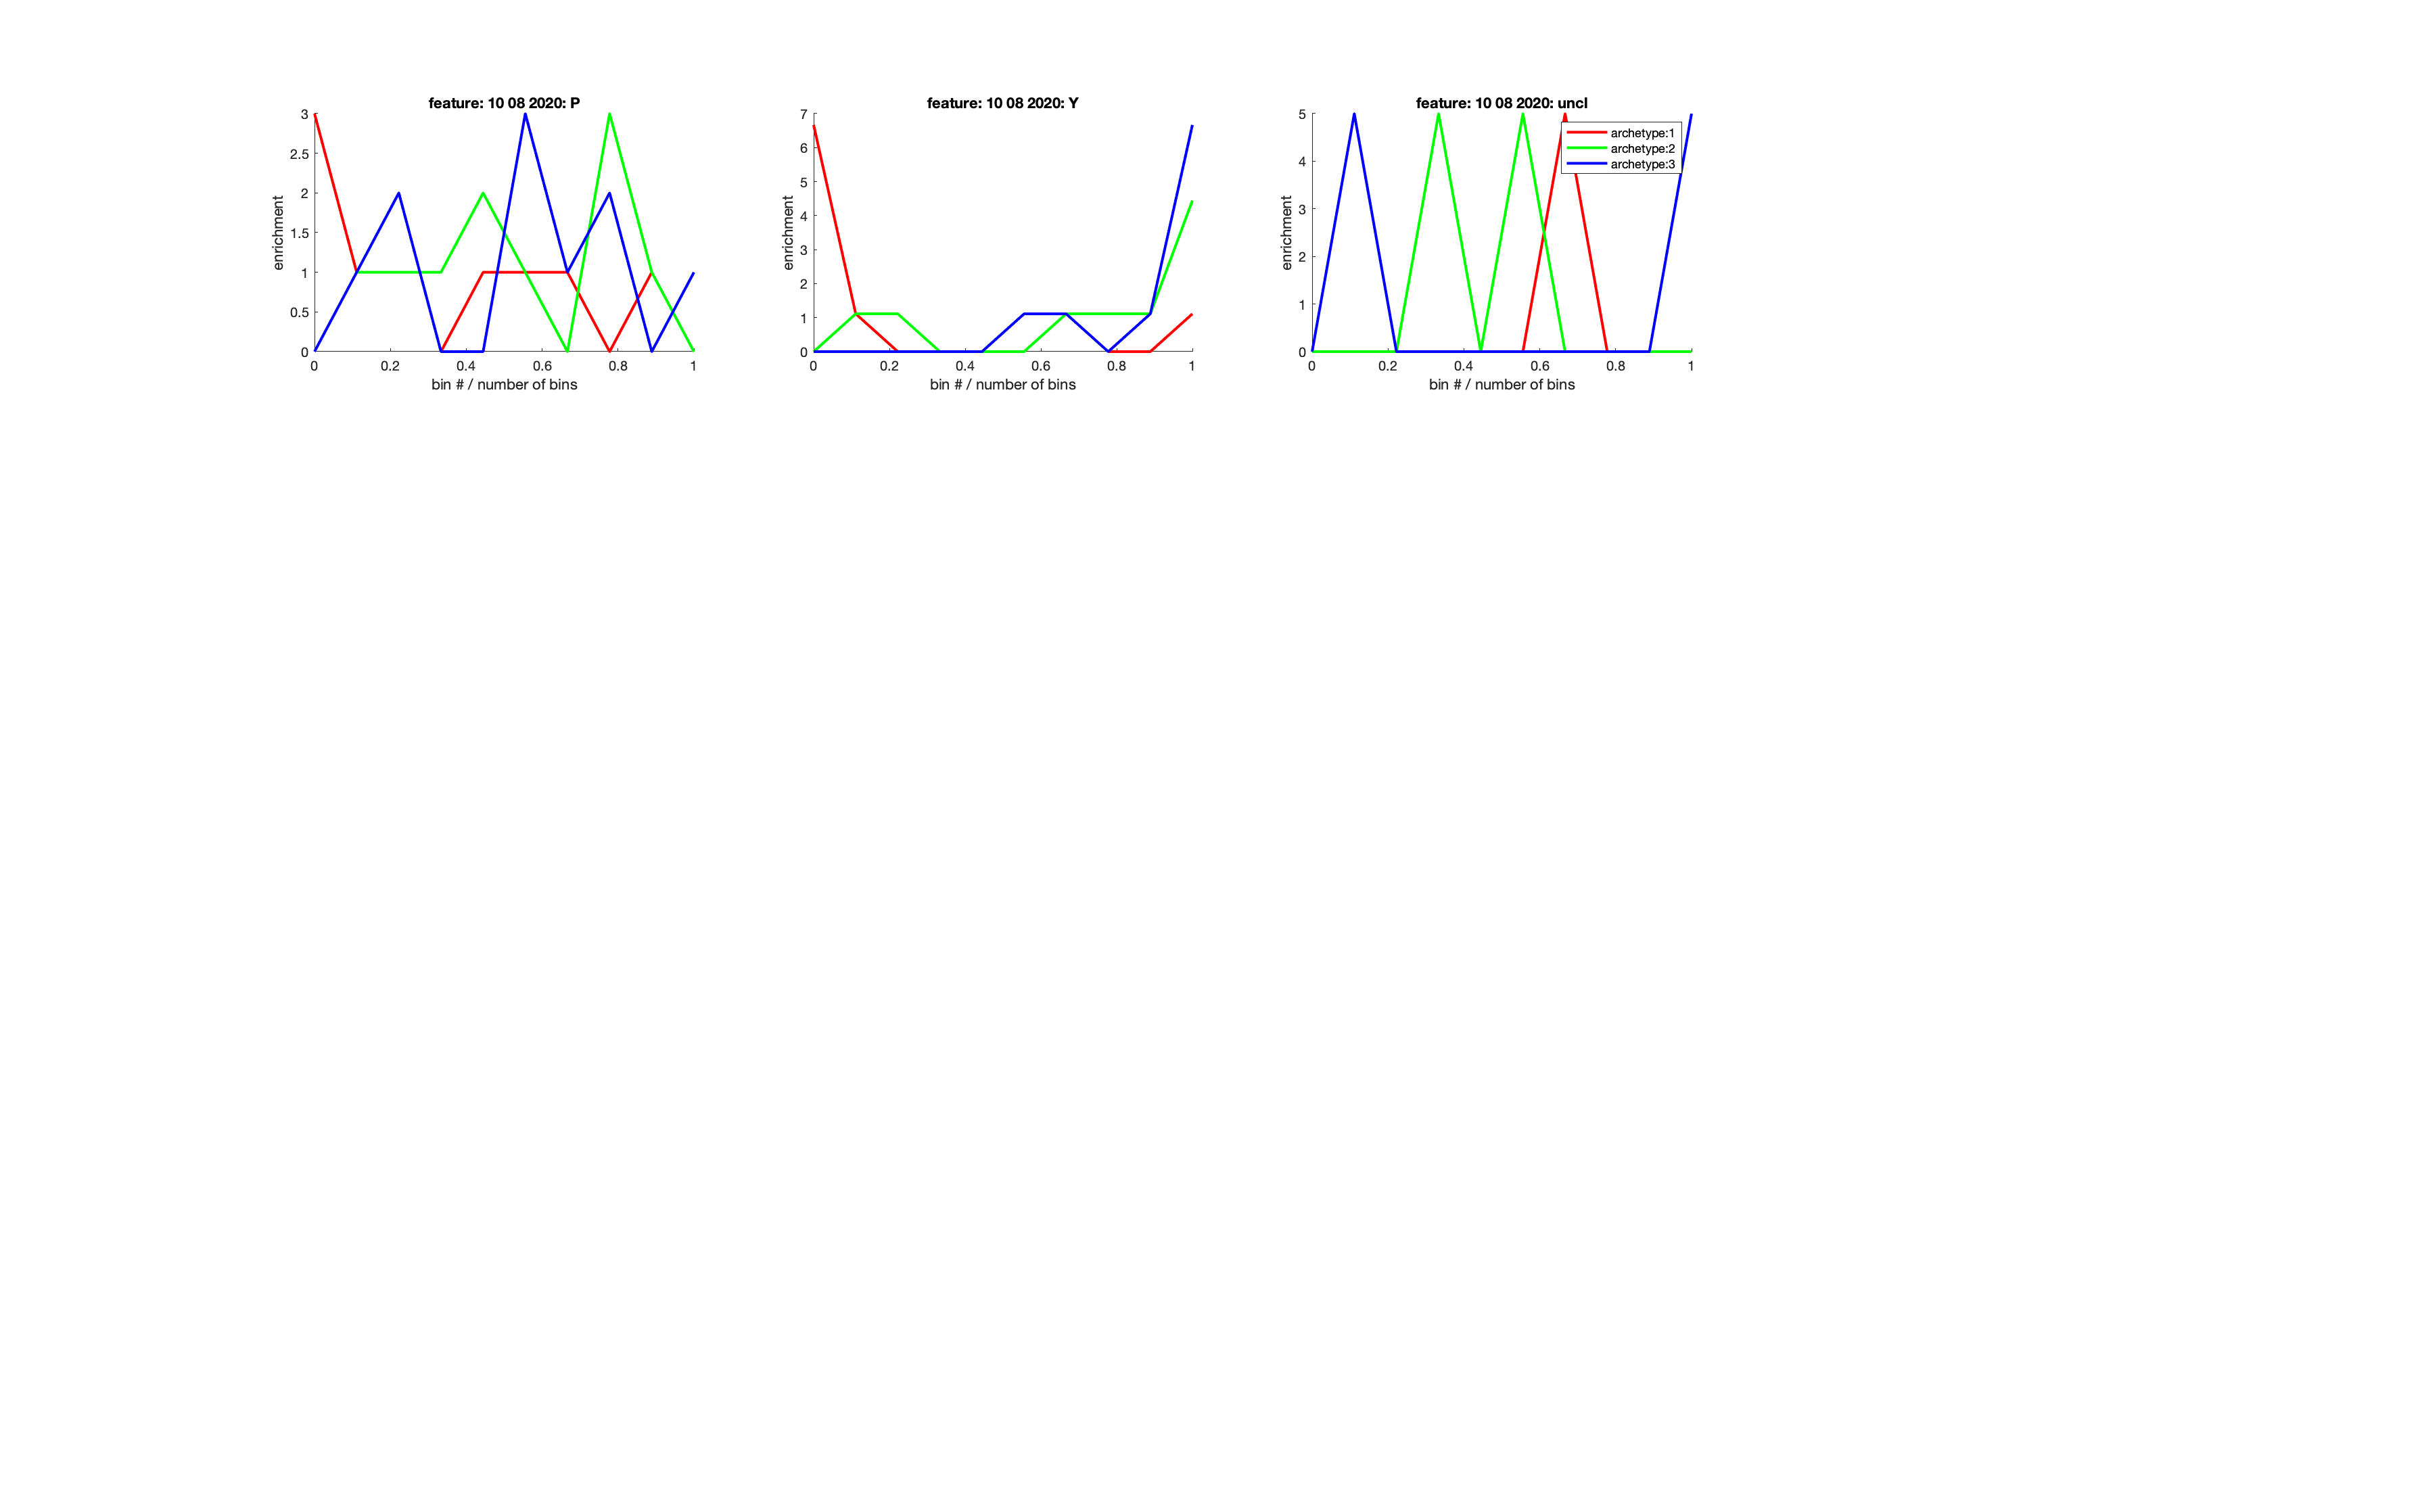

Finished computing discrete enrichments.
Finished computing continuous enrichments.
*** Wrote summary of enriched discrete features to __discrete_significant.csv
*** Wrote summary of enriched continuous features to __continuous_significant.csv


discrAttrNames = regexprep(discrAttrNames, '_', ' ');
contAttrNames = regexprep(contAttrNames, '_', ' ');
[arc_lite, arcFinal2, pc_lite] = ParTI_lite(geneExpression, 5, 12, discrAttrNames, ...
    discrAttr, 0, transpose(geneNames), geneExpression, [], 0.1, '_');

[arc_lite, arcFinal2, pc_lite] = ParTI_lite(geneExpression, 5, 12, discrAttrNames, ...
    discrAttr, 0, transpose(geneNames), geneExpression, [], 0.1, '_');

## We are now ready to perform Pareto Task Inference.

We use the Sisal algorithm (1), with up to 8 dimensions. We provide the discrete patient attributes, and ask ParTI to preliminary booleanize these attributes (0). We also pass continuous patient attributes. We pass a boolean matrix specifiying which genes each continuous feature is baesd on (to be used in the leave-one-out procedure). We specify that the enrichment analysis will be performed with a bin size of 5%. Finally, the output of the the analysis will be stored in an Excel spreadsheet, under the name 'CancerRNAseq_enrichmentAnalysis_*.csv'. 5 is PCHA

[arc_lite, arcFinal, pc_lite] = ParTI_lite(geneExpression, 5, 12, discrAttrNames, ...
    discrAttr, 0, transpose(geneNames), geneExpression, [], 0.1, '_');

## Finally, we perform the compete analysis, including randomization

controls and archetype error estimation.

[arc, arcFull, pc, errs, pval, coefs] = ParTI(geneExpression, 5, 10, discrAttrNames, ...
    discrAttr, 0, contAttrNames, contAttr,[], 0.1, 'Bulk_PCHA_full');
